Playing hood_f.wav at 24000 Hz with duration 0.24 seconds and 5791 samples


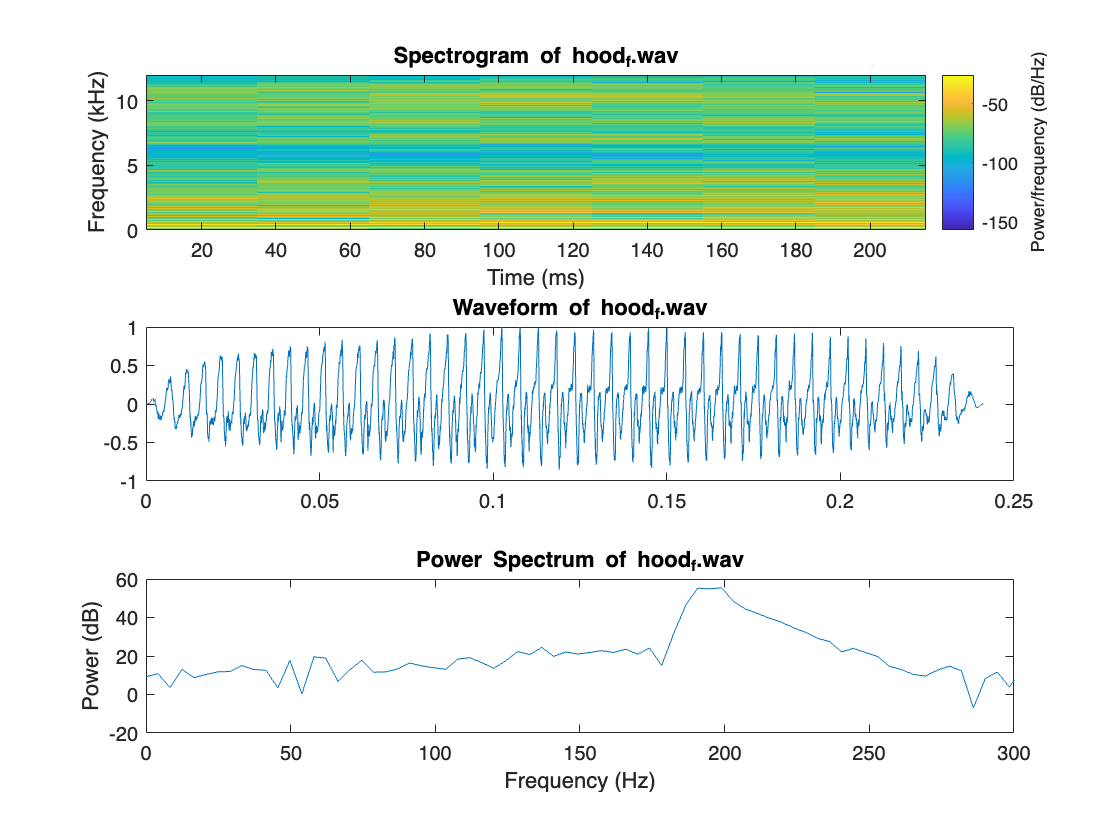

file_1 = 'hood_f.wav';
[audio, fs, duration, numSamples] = playAudio(file_1);

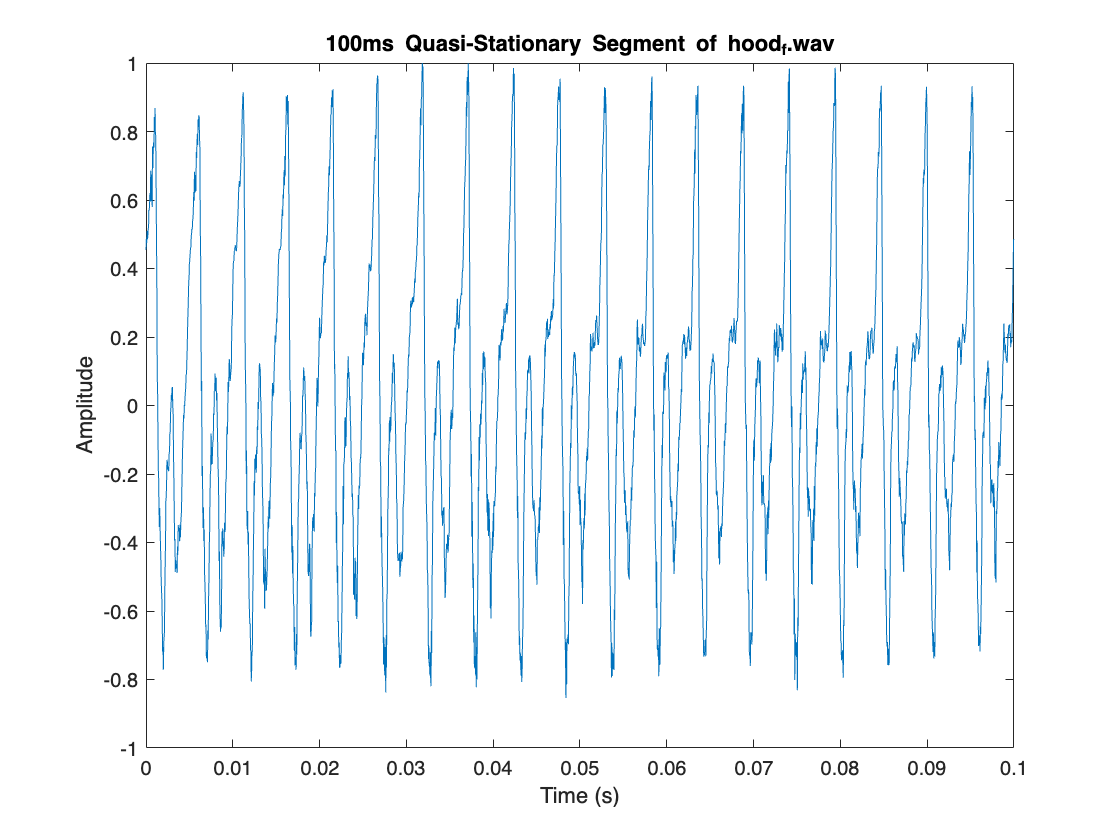

% select a 100ms quasi-stationary segment
segmentDuration = 0.1;
segment = extractCenterSegment(audio, fs, segmentDuration, file_1);

lpcOrder = 12;
estimateLPC(segment, lpcOrder);

LPC Coefficients (order 12):
    1.0000   -1.1053   -0.3781    0.3227    0.5582   -0.3619   -0.0737   -0.3582    0.6760   -0.0484   -0.2548   -0.1602    0.2312



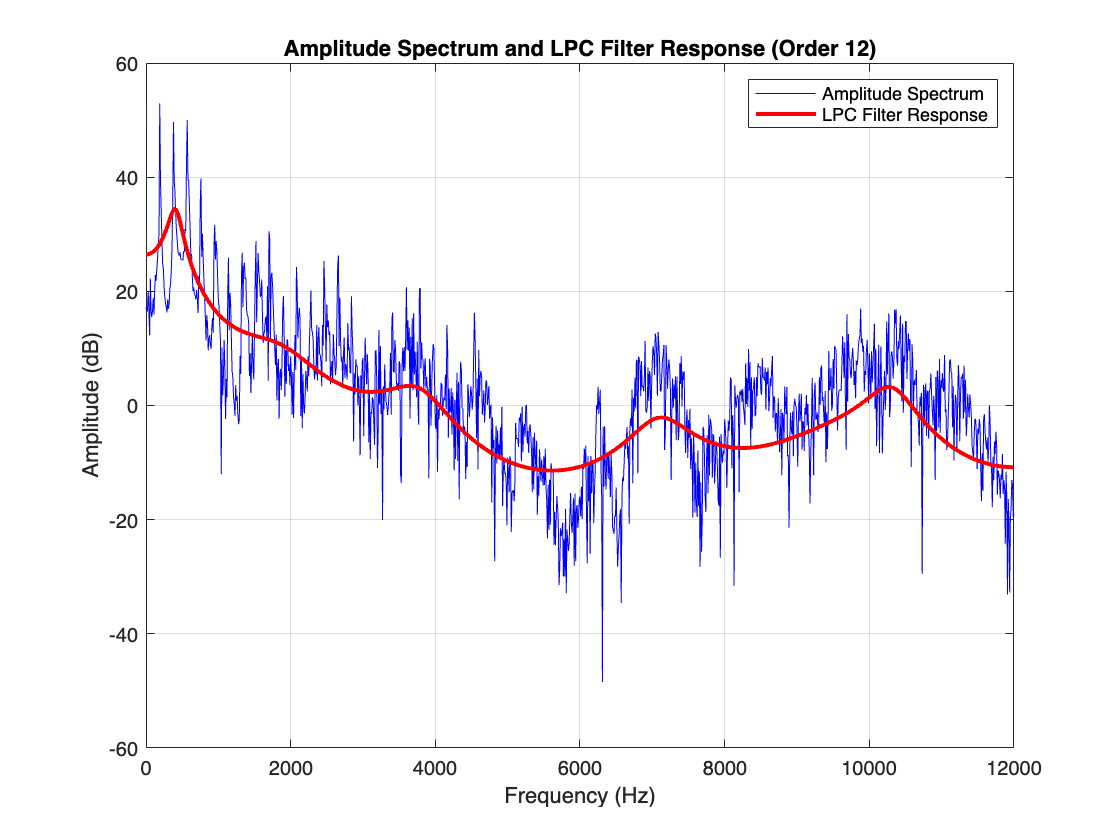

Estimated Formant Frequencies (Hz):
F1: 398.44 Hz
F2: 3644.53 Hz
F3: 10265.62 Hz
DC Component: 17.23 dB
Estimated F0: 190.00 Hz


[formants, f0_estimate] = plotLPCResponse(segment, fs, lpcOrder);

f0 = mean(pitch(segment, fs, 'Range', [50 200]));
fprintf('Estimated F0 using pitch function: %.2f Hz\n', f0);

Estimated F0 using pitch function: 190.49 Hz


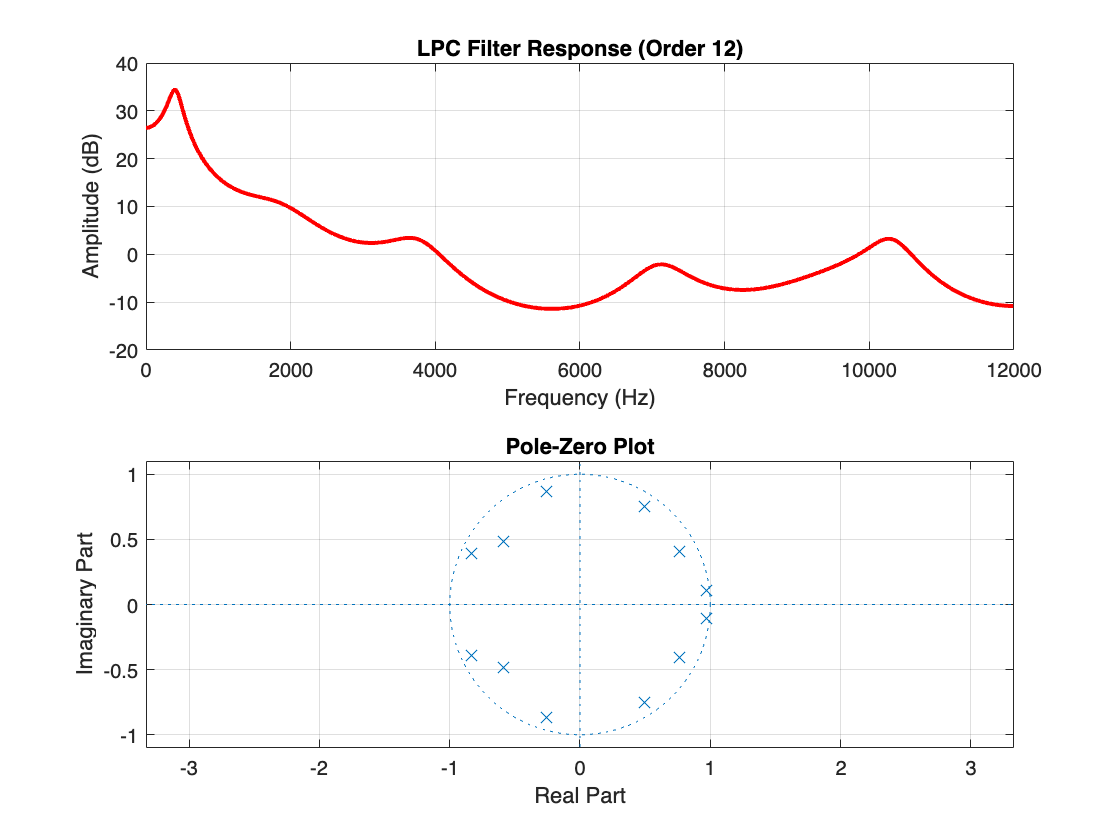

plotLPCPoleZero(segment, fs, lpcOrder);

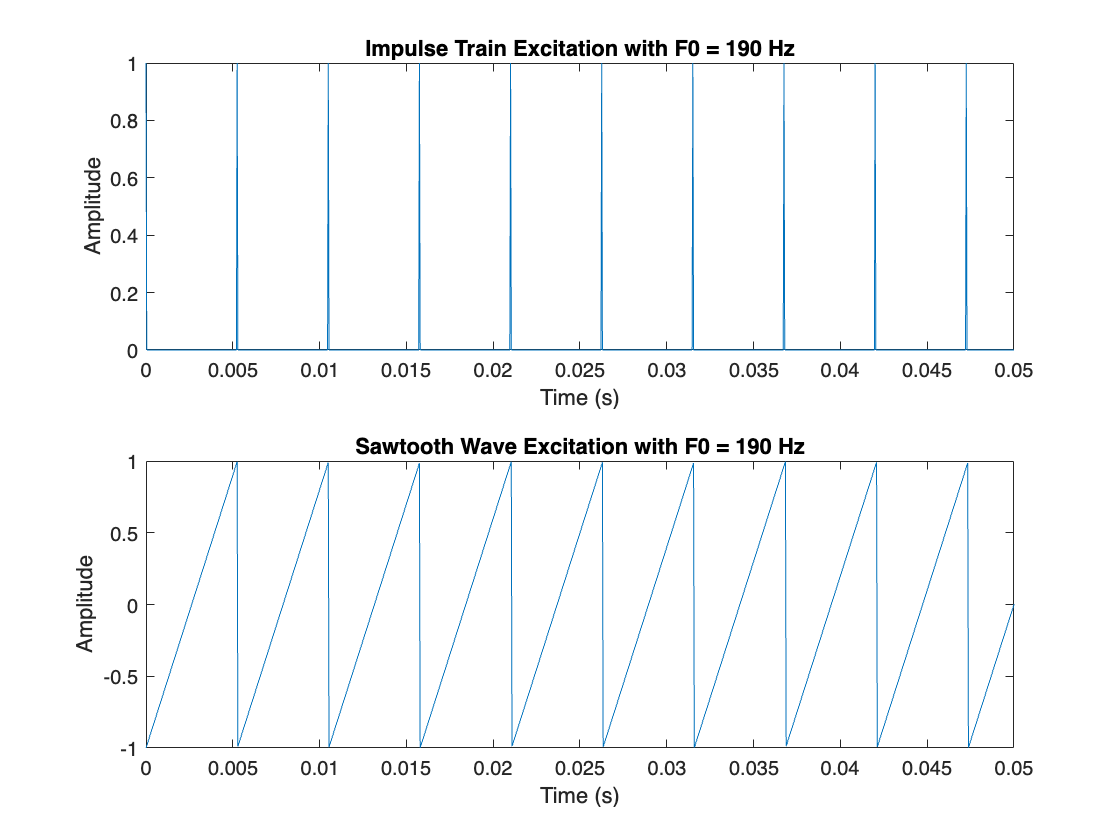

synthesizeLPC(segment, fs, f0_estimate, lpcOrder, synthesis_duration)